## 1. Problema das faltas

pfoi = 0.7;
pfaltou = 0.8;


    a)

%foi na sexta  = 0.7 --> foi na quarta = 0.7
%nao foi na sexta = 0.3 --> foi na quarta = 0.8


prob_a = 0.7*0.7+0.3*0.8;
fprintf('Probabilidade de ir na quarta seguinte = %.4f', prob_a);

Probabilidade de ir na quarta seguinte = 0.7300

T = [0.7 0.8;
     0.3 0.2];
%1 nao falotu

x0 = [1;0];
% X2 = T * X1 = T * X(k-1)
%x2 = T * (T*x0);
x2 = T^2*x0;

%como quero a prob de estar presente, valor ==1
prob_presenca = x2(1);
fprintf('Probabilidade por matriz = %.4f', prob_presenca);

Probabilidade por matriz = 0.7300

    b) Probabilidade estar numa quarta depois de não ir na anterior

x0 = [0;1];

x2 = T^2*x0;
prob_presenca = x2(1);
fprintf('Probabilidade por matriz = %.4f', prob_presenca);

Probabilidade por matriz = 0.7200

    c) Ir à ultima aula sabendo que foi à primeira

x0 = [1;0];

x29 = T^29*x0;
prob_presenca_d = x29(1);
fprintf('Probabilidade por matriz = %.4f', prob_presenca_d);

Probabilidade por matriz = 0.7273

d) Gráfico odds ir às auilas com odds iniciais

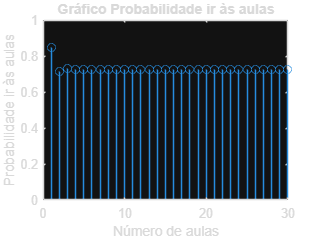

n_aulas = 30;
prob_1 = [0.85 ; 0.15];
prob_ir = zeros(1,n_aulas);
x0 = [0.85;0.15];

for i = 1:n_aulas
    xn = T^(i-1)*x0;
    prob_ir(i) = xn(1);
end

stem(1:n_aulas,prob_ir);
title('Gráfico Probabilidade ir às aulas');
xlabel('Número de aulas');
ylabel('Probabilidade ir às aulas');